clear 

FileTable = [
'01_01.mat';
'01_02.mat';
'02_01.mat';
'03_01.mat';
'04_01.mat';
'05_01.mat';
'07_01.mat';
'08_01.mat';
'09_01.mat';
'10_01.mat';
'12_01.mat';
'13_01.mat';
'14_01.mat';
'15_01.mat';
'17_01.mat';
'18_01.mat';
'19_01.mat';
'20_01.mat';
'21_01.mat';
'22_01.mat';
'23_01.mat';
'24_01.mat';
'25_01.mat';
'26_01.mat';
'27_01.mat';
'28_01.mat';
'28_02.mat';
'29_01.mat';
'30_01.mat';
'32_01.mat';
'33_01.mat';
'34_01.mat';
'35_01.mat';
];
Nfile = size(FileTable,1); 
DirName = './W203_4';


Ntype  = 4;
Nvalue = 10;
AnalysisData = zeros(Nfile*Ntype,Nvalue);

for iFile = 1:Nfile
    FileName = FileTable(iFile,:);
    % Point Num Aver Median Std Max Min CI_Upper CI_lower
    AnalysisData((iFile - 1) * Ntype + 1: iFile * Ntype,:) = Analysis(DirName,FileName);
end

FileName = '01_01.mat'

ans = 	1.0e+05 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.5951 + 6.2877i


FileName = '07_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.9914 + 6.9621i


FileName = '08_01.mat'

ans = 	1.0e+05 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.1457 + 1.9945i


FileName = '12_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.7443 + 2.4579i


FileName = '13_01.mat'

ans = 	1.0e+06 *

   0.0008 + 0.0000i
   0.0008 + 0.0000i
   0.0003 + 0.0000i
   4.5516 + 2.9528i


FileName = '14_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   5.1825 + 1.2432i


FileName = '17_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.9929 + 3.5623i


FileName = '19_01.mat'

ans = 	1.0e+05 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   6.0449 + 3.7357i


FileName = '20_01.mat'

ans = 	1.0e+05 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   8.4656 + 4.1553i


FileName = '24_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   3.8744 + 1.6917i


FileName = '25_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   4.6807 + 8.6397i


FileName = '28_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   1.2433 + 2.2362i


FileName = '28_02.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   9.9416 + 5.6697i


FileName = '30_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   4.0944 + 2.1845i


FileName = '33_01.mat'

ans = 	1.0e+07 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   2.3281 + 1.7166i


FileName = '34_01.mat'

ans = 	1.0e+04 *

   0.0009 + 0.0000i
   0.0009 + 0.0000i
   0.0009 + 0.0000i
   0.0005 + 8.2102i


FileName = '35_01.mat'

ans = 	1.0e+06 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.1820 + 1.4590i


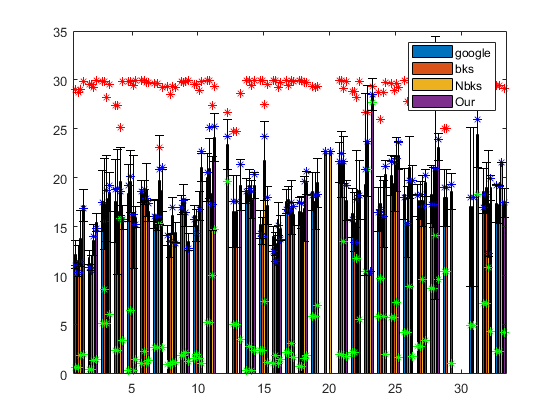

% Point Num Aver Median Std Max Min CI_Upper CI_lower
jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jPoint, jNum, jAver, jMed, jStd, jMax, jMin, jCI_Upper, jCI_lower, jHdop] = jIndex{:};

x=1:Nfile;
figure
PlotAnalysisDataAver = reshape(AnalysisData(:,jAver),Ntype,[])';
b = bar([1:Nfile], PlotAnalysisDataAver(:,:));
xbar = [b(1).XEndPoints' b(2).XEndPoints' b(3).XEndPoints' b(4).XEndPoints'];
hold on

p1=plot(xbar, reshape(AnalysisData(:,jMax),Ntype,[])','r*');
p2=plot(xbar, reshape(AnalysisData(:,jMin),Ntype,[])','g*');
p3=plot(xbar, reshape(AnalysisData(:,jMed),Ntype,[])','b*');

errorbar(xbar,reshape(AnalysisData(:,jAver),Ntype,[])', ...
    reshape(AnalysisData(:,jCI_lower),Ntype,[])' - reshape(AnalysisData(:,jAver),Ntype,[])', ...
    reshape(AnalysisData(:,jCI_Upper),Ntype,[])'-reshape(AnalysisData(:,jAver),Ntype,[])',...
    'black','Linestyle', 'None');
legend([b(1) b(2) b(3) b(4)],{'google','bks','Nbks','Our'});
% legend(p2,'Max');

hold off


% hdop
figure
b = bar([1:Nfile],reshape(AnalysisData(:,jHdop),Ntype,[])');

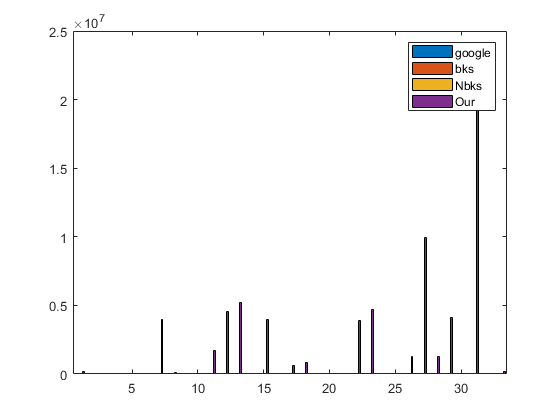

legend([b(1) b(2) b(3) b(4)],{'google','bks','Nbks','Our'});

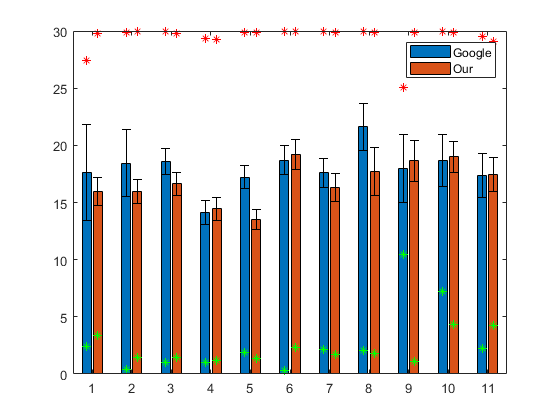

PlotSerial = [1 4]; % Google Our
PlotFile   = [4 5 6 8 9 14 17 21 29 32 33];

% Point Num Aver Median Std Max Min CI_Upper CI_lower
jIndex = {1 2 3 4 5 6 7 8 9 10 11};
[jPoint, jNum, jAver, jMed, jStd, jMax, jMin, jCI_Upper, jCI_lower, jHdop] = jIndex{:};

x=1:length(PlotFile);
figure
PlotAnalysisDataAver = reshape(AnalysisData(:,jAver),Ntype,[])';
PlotAnalysisDataAver = PlotAnalysisDataAver(PlotFile, PlotSerial) ;
b = bar(x, PlotAnalysisDataAver);
xbar = [b(1).XEndPoints' b(2).XEndPoints'];
hold on


PlotAnalysisDataMax = reshape(AnalysisData(:,jMax),Ntype,[])';
PlotAnalysisDataMin = reshape(AnalysisData(:,jMin),Ntype,[])';
PlotAnalysisDataMed = reshape(AnalysisData(:,jMed),Ntype,[])';
PlotAnalysisDataMax = PlotAnalysisDataMax(PlotFile, PlotSerial) ;
PlotAnalysisDataMin = PlotAnalysisDataMin(PlotFile, PlotSerial) ;
PlotAnalysisDataMed = PlotAnalysisDataMed(PlotFile, PlotSerial) ;

p1=plot(xbar, PlotAnalysisDataMax,'r*');
p2=plot(xbar, PlotAnalysisDataMin,'g*');
% p3=plot(xbar, PlotAnalysisDataMed(:,[1 4]),'b*');


PlotAnalysisDataCI_lower = reshape(AnalysisData(:,jCI_lower),Ntype,[])';
PlotAnalysisDataCI_Upper = reshape(AnalysisData(:,jCI_Upper),Ntype,[])';
PlotAnalysisDataCI_lower = PlotAnalysisDataCI_lower(PlotFile, PlotSerial) ;
PlotAnalysisDataCI_Upper = PlotAnalysisDataCI_Upper(PlotFile, PlotSerial) ;

errorbar(xbar,PlotAnalysisDataAver, ...
    PlotAnalysisDataCI_lower - PlotAnalysisDataAver, ...
    PlotAnalysisDataCI_Upper - PlotAnalysisDataAver,...
    'black','Linestyle', 'None');
legend([b(1) b(2)],{'Google','Our'});

hold off